# 2020-11-18-Jiahao

% Run
input_path = 'E:\2020-11-18-Jiahao\';
tile_block = [3072 3072 25 4 2];
gpu_block = [1024 1024 25 4 2];
useGPU = false;

starting = tic;

% Output path
curr_out_path = fullfile(input_path, 'output');

if ~exist(curr_out_path, 'dir')
    mkdir(curr_out_path)
end

tic;

sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
sdata = sdata.LoadRawImages('output_class', "cell");

tile_idx = BlockTest(sdata.rawImages{1}, tile_block, 0);
NtileBlock = numel(tile_idx)

upd = textprogressbar(NtileBlock, 'updatestep', 1);

total_Spots = [];
total_Reads = {};
    
for i =1:NtileBlock
    current_idx = tile_idx{i}
    fprintf(sprintf("====Current Tile: %d====\n", i));
    fprintf(sprintf("Index: %d - %d - %d - %d\n", current_idx));
    
    tdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    tdata = tdata.LoadDim(tile_block);
    tdata.rawImages = {};
    
    for i=1:numel(sdata.rawImages)
    tdata.rawImages{i} = sdata.rawImages{i}(current_idx(1,1):current_idx(1,2), current_idx(2,1):current_idx(2,2), :,:);
    end
    
    tdata.rawImages = im_cell2mat(tdata.rawImages);

    % Preprocessing
    tdata = tdata.HistEqualize('Method', "inter_round");
    tdata = tdata.HistEqualize('Method', "intra_round");
    tdata = tdata.MorphoRecon('Method', "2d", 'radius', 3);
    
    % % Thresholding
    curr_bw = (50 > tdata.rawImages) & (tdata.rawImages > 0);
    tdata.rawImages(curr_bw) = 0;
    
    % Log
    tdata.log = fopen(fullfile(curr_out_path, sprintf('log_%d.txt', i)), 'w');
    
    % Image registration
    tdata = tdata.test_GlobalRegistration('useGPU', false);
    
    gpu_overlap = 0;
    gb_idx = BlockTest(tdata.rawImages, gpu_block, gpu_overlap);
    NgpuBlock = numel(gb_idx)
        
    for j=1:NgpuBlock
        
        bdata_start = tic;
        gpu_idx = gb_idx{j}
        
        fprintf(tdata.log, sprintf("====Current Block: %d====\n", i));
        fprintf(tdata.log, sprintf("Index: %d - %d - %d - %d\n", gpu_idx));
        
        bdata = new_STARMapDataset(input_path, 'useGPU', true);
        bdata.log = tdata.log;
        bdata = bdata.LoadDim(gpu_block);
        bdata.registeredImages = gpuArray(tdata.registeredImages(...
            gpu_idx(1,1):gpu_idx(1,2),...
            gpu_idx(2,1):gpu_idx(2,2),...
            :,:,:));
        
        bdata = bdata.LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);
         
        % replace the old image 
        tdata.registeredImages(...
            gpu_idx(1,1):gpu_idx(1,2),...
            gpu_idx(2,1):gpu_idx(2,2),...
            :,:,:) = bdata.registeredImages;
       
    end
    
%     % Save registered image
%     output_dir = fullfile(curr_out_path, 'registered_image');
%     if ~exist(output_dir, 'dir')
%        mkdir(output_dir);
%     end
%     new_SaveImg(output_dir, sdata.registeredImages);
    
    % Finding the dots 
    input_img = tdata.registeredImages;
    
    quality_factor = 0;
    volume_threshold = 1;
    showPlots = false;
     
     
    Nround = size(input_img, 5);
    
    allSpots = [];
    allReads = {};
    basecsMat = [];
    allScores = [];
    
    local_threshold = quality_factor;
    
    % get barcode for each pixel
    [base_call_stack, quality_matrix, round_quality_matrix, barcodes] = GetBarcodes(input_img, local_threshold, false); % 
    mean_quality_matrix = mean(round_quality_matrix, 4);
    
    % get global quailty
    base_call_qual = quality_matrix(quality_matrix ~= 0);
    base_call_qual = reshape(base_call_qual, 1, numel(base_call_qual));
    
    % get global quailty threshold
    quality_threshold = quality_factor * max(quality_matrix, [], 'all');
    fprintf('The global quality score threshold for barcode calling is: %4.2f \n', quality_threshold)
    
    % iterate through correct barcode clusters
    props = {'Volume'; 'Centroid'; 'VoxelIdxList'};
    
    all_volume = []; 
    fprintf('Iterate through clusters...')
    
    iter_codes = barcodes;
    
    
    parfor c = 1:numel(iter_codes)
    
        curr_barcode = iter_codes(c); 
    
        curr_img = zeros(size(base_call_stack)); 
        curr_img(base_call_stack == curr_barcode & quality_matrix > quality_threshold) = 1; % global quality filtration 
        curr_img = logical(curr_img);
    
    
        curr_stats = regionprops3(curr_img, props);
        all_volume = [all_volume; curr_stats.Volume]; %% WARNING
        curr_valid_stats = curr_stats(curr_stats.Volume > volume_threshold, ["Centroid", "VoxelIdxList"]); % volume filtration
        curr_valid_cc = int16(curr_valid_stats.Centroid);
        if ~isempty(curr_valid_cc)    
            Nspots = size(curr_valid_cc, 1);
            allSpots = [allSpots; curr_valid_cc]; %% WARNING
            curr_barcode = Colorseq2Str(curr_barcode);
            curr_read = repelem({curr_barcode}, Nspots, 1);
            allReads = [allReads; curr_read];
            curr_mat = reshape(curr_barcode, [Nround, 1]);
            curr_mat = arrayfun(@str2double, curr_mat);
            curr_mat = repmat(curr_mat', [Nspots, 1]);
            basecsMat = [basecsMat; curr_mat];
            
            for i=1:Nspots
                curr_spot = curr_valid_stats.VoxelIdxList{i};
                curr_score = mean_quality_matrix(curr_spot);
                curr_score = mean(curr_score);
                allScores = [allScores; curr_score];
            end
        end
    
    end
    
    block_offsets = [current_idx(2,1) - 1 current_idx(1,1) - 1 0]
    if size(allSpots, 1) ~= 0
        block_offsets = repmat(block_offsets, size(allSpots, 1), 1);
        allSpots = allSpots + int16(block_offsets);
    end
    
    % Update tile reads
    total_Spots = [total_Spots; allSpots];
    total_Reads = [total_Reads; allReads];

            
    upd(i);
end


% Plot
saveAS = true;
img_path = fullfile(input_path, "round1", "TileScan 003_TileScan_001_Merging_z00_ch04.tif");
img = new_LoadMultipageTiff(img_path, 'uint8', 'uint8', false);
img = max(img, [], 3);
% img = img(1:3072, 1:3072);

total_Reads = cellfun(@str2double, total_Reads);

img_show = cat(3, zeros(size(img), 'uint8'), zeros(size(img), 'uint8'), imadjust(img, [0 0.1]));

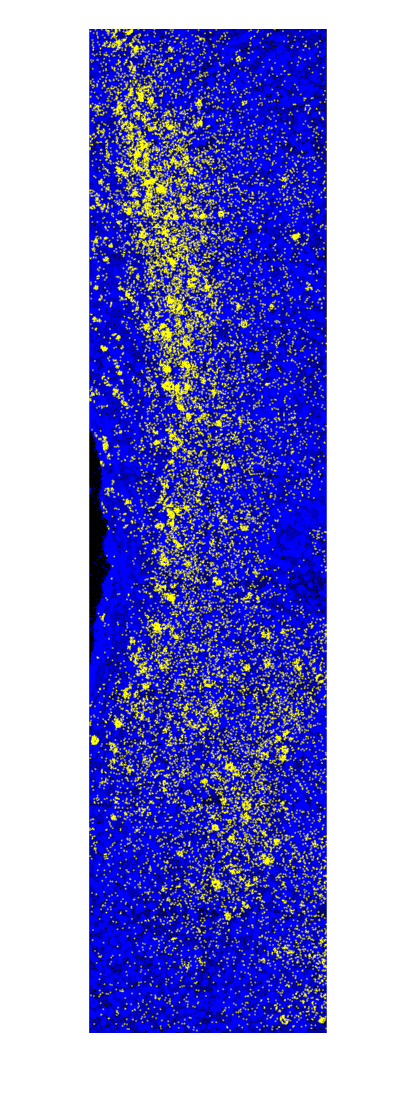

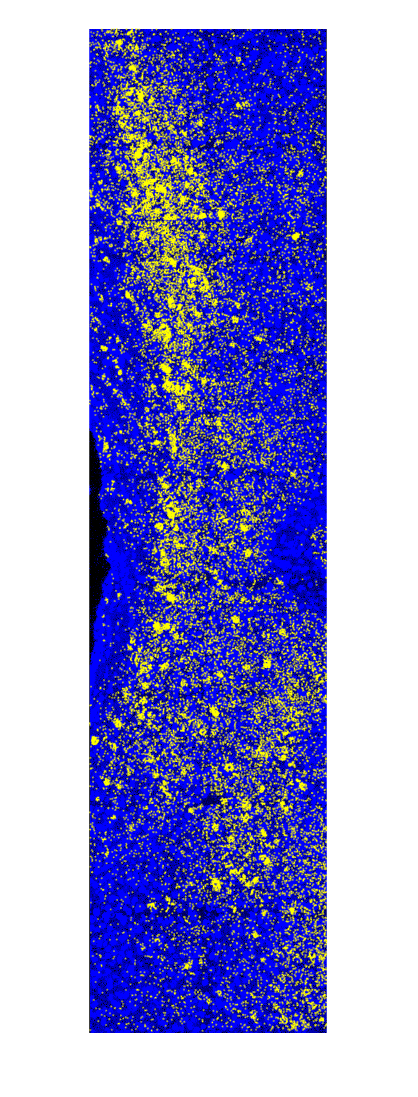

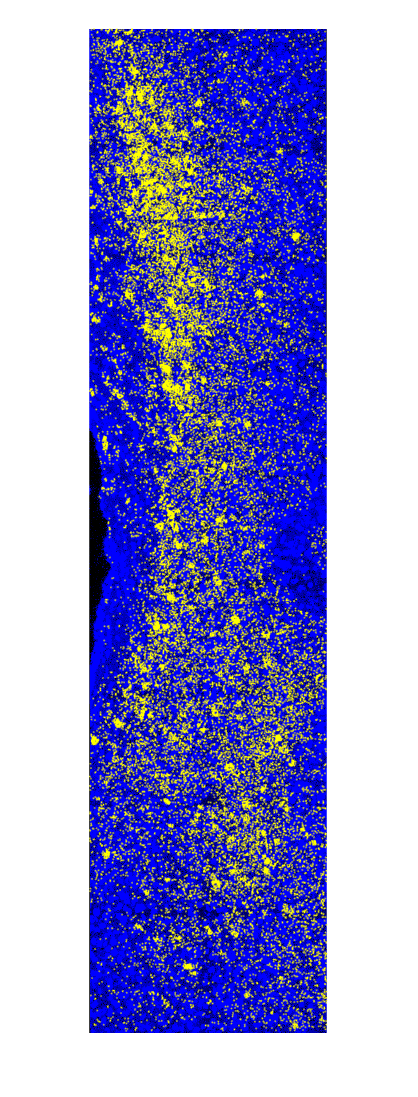

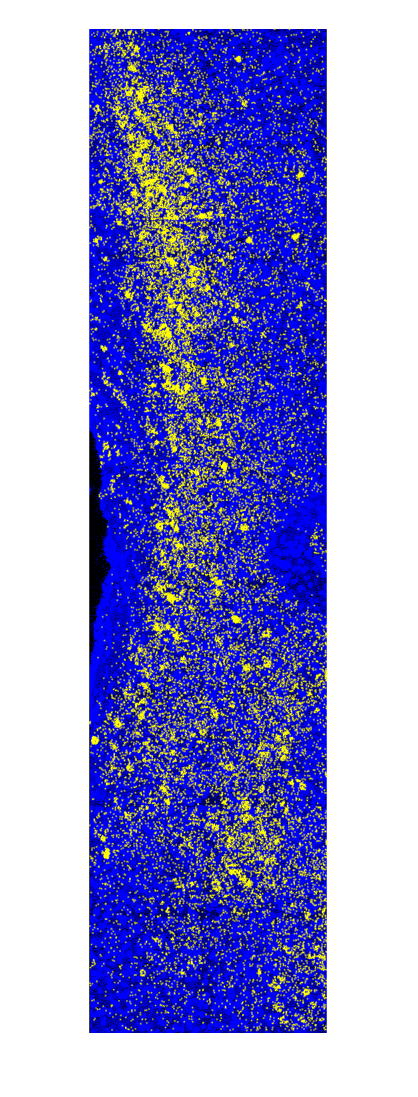

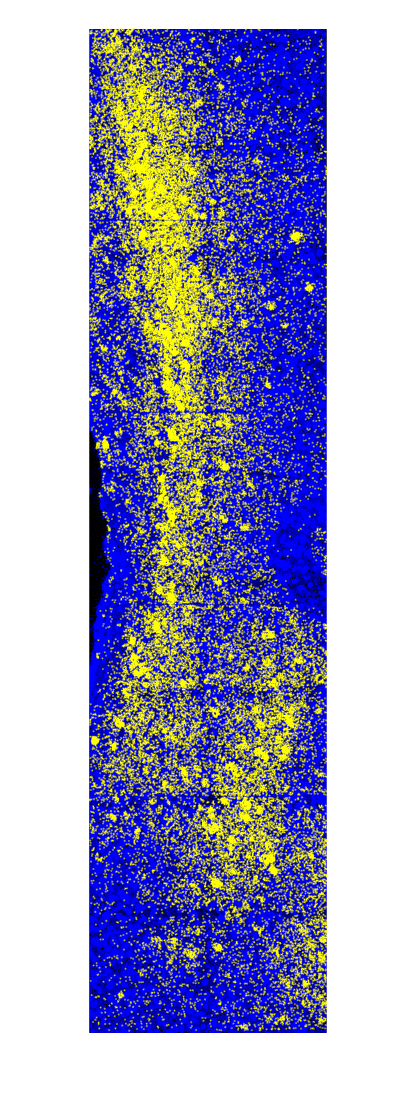

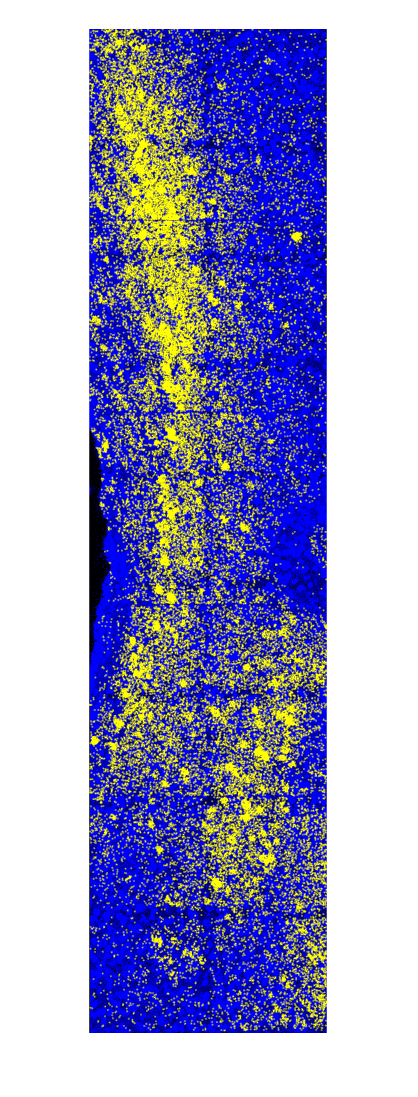

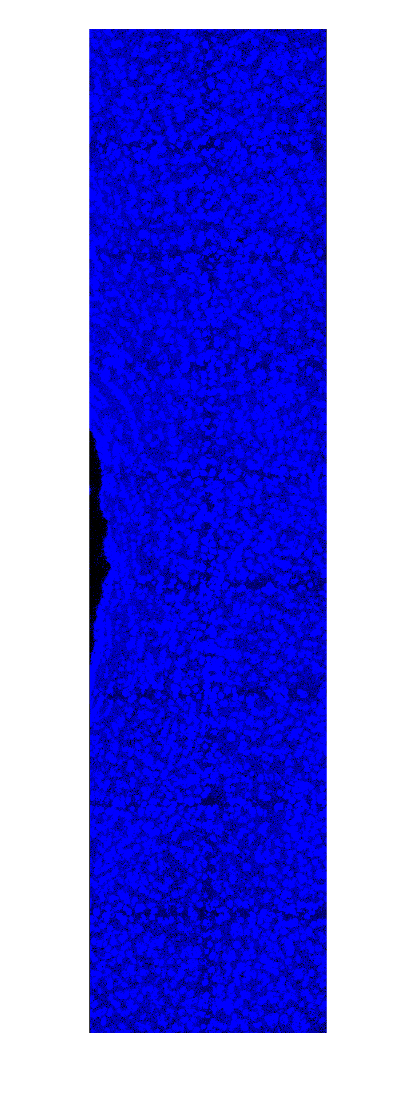


for i=1:numel(barcodes)
    curr_barcode = barcodes(i);
    curr_reads = total_Reads == curr_barcode;
    curr_spots = total_Spots(curr_reads, :);
    
    fh = figure; 
    %ah = axes('Units','Normalize','Position', [0 0 1 1]);
    imshow(img_show, [])
    hold on
    plot(curr_spots(:,1), curr_spots(:,2), '.', "Color", 'yellow', "MarkerSize", 1)
    % input_title = sprintf("Color Code: %d", curr_barcode);
    % title(input_title)
    hold off
    %axis(ah, 'square');
    % fh.Position(3) = fh.Position(4);
    
    
    if saveAS
        fig_name = fullfile(curr_out_path, sprintf("%d.pdf", curr_barcode));
        saveas(gcf, fig_name)
    end
    
end



% Save dots
save(fullfile(curr_out_path, 'allPoints.mat'), "total_Reads", "total_Spots");

fprintf(sprintf('[time = %.2f s]\n', toc));

reset(gpuDevice)